# Array of spheres

- Date:       6/11/2019

options.mph_file_version = 7;

This option is designed to controll which geometry etc changes are made.

%options.resonator_type = "slab";
%options.resonator_type = "slab-dimer";
options.resonator_type = "sphere";
%options.resonator_type = "soljacic";
%options.resonator_type = "random";

Which type of non-linear generation is being simulated.  The external current density will be changed for SHG andDFG.

options.non_linear = "SFG";
%options.non_linear = "SHG";
%options.non_linear = "DFG";

## Purpose of study

Study of how the BICs disapear at the diffraction limit.

It might take several different studies to get the results needed, so which should be run can be set with the `switch` statement.

case_num = "2";

switch case_num
    

### Eigenfrequencies

The first this I need to do is locate all of the BICs, which can be found by looking for eigenfrequencies with very high quality factors.

I'll just use the default values in the file for the first run.

    case "1"
        options = set_study("Eigenfrequency", options, case_num);
            
        options.studies("Eigenfrequency",:).NumberEigenfreqs = "10";
        

### Scattering efficiency

I found a BIC at 1548.94 nm, so do a scattering efficiency study around this wavelength

Also include some plot from the previous study to explain why I am doing this study:

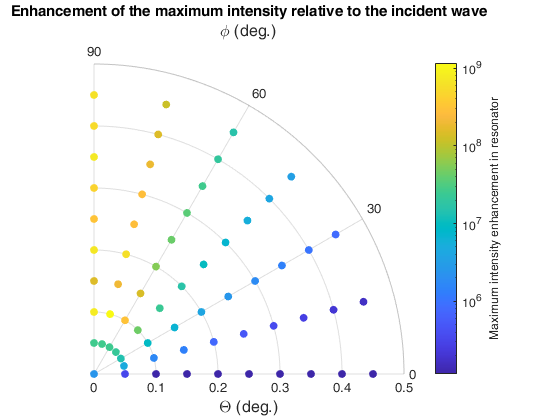

    case "2"
        options = set_study("EWFD: Signal", options, case_num);
        
        % The number of frequencies to calculate.  With my file the minimum
        % is two due to an inner solution.
        options.parameters("ind_max",:).Value = "2";
        
        options.parameters("lda_p",:).Value = "1550[nm]/2";
        options.parameters("lda_s",:).Value = "1548.9[nm]";
        options.parameters("lda_s_max",:).Value = "1548.97[nm]";
        options.parameters("ind_max",:).Value = "71";
    otherwise
            error(['Unknown configuration number in switch/case',...
                ' statement in setup_comsol.mlx\n']);
end

options.save_progress_log = false; % Large file!

function options = set_study(study_name, options, case_num)
    

Which study to run.

    options.study = study_name;
    
    options = set_default_options(options);
    options.output_dir = [options.base_data_dir 'sphere\sphere_algaas_'...
        matlab.lang.makeValidName(['case_' num2str(case_num)]) '\'];
    if ~isempty(options.base_data_dir_final)
        options.output_dir_final = [options.base_data_dir_final 'sphere\sphere_algaas_'...
            matlab.lang.makeValidName(['case_' num2str(case_num)]) '\'];
    else
        options.output_dir_final = '';
    end
end